## Robust and Nonlinear Control, EEN050. 

### Assignment 3 on robust controller design.

Check NS for the nominal plant. System is stable if there are no RHP poles.

isstable(Gn*K_hinf)

ans = logical
   1


Find the TF used to check NP, RS, RP.  We check the submatrices of N for NP and RS. The whole N gives RP.

N11_w = N_hinf_w(1:2,1:2); % check for RS
N22_w = N_hinf_w(3:6,3:8); % check for NP
hinfnorm(N11_w)

ans = 0.4734

hinfnorm(N22_w)

ans = 22.5220

hinfnorm(N_hinf_w)

ans = 22.6428

Plot singular value diagrams.

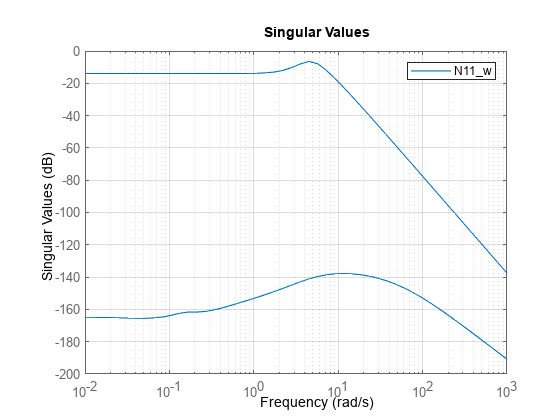

w = logspace(-2, 3);
sigma(N11_w, w), grid on, legend

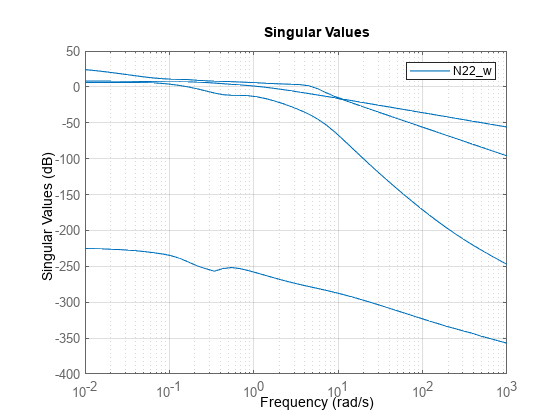

sigma(N22_w, w), grid on, legend

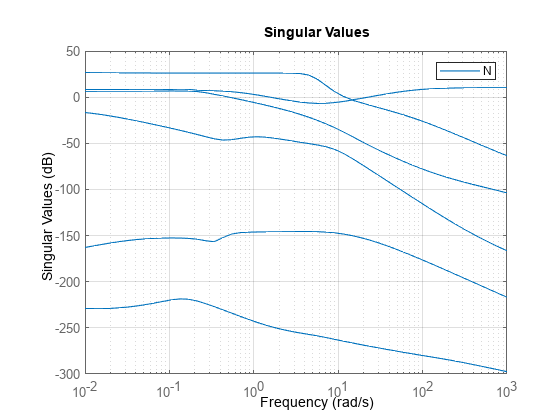

sigma(N_hinf_w, w), grid on, legend("N")

Conditions satisfied for $\omega \in [0.01, 1000]$.

For N11 only.

Comparing the three different controllers.

Construct the time and reference vectors.

t = 0:0.01:50; % 50 s with 10 ms resolution => 5001 samples
r = [-0.5*ones(1,1000), ones(1,1000), 5*ones(1,1000),... 
    -2*ones(1,1000), zeros(1,1001)];

### First compare the controllers without any noise or distrubance

Re-create N for the controllers with the simplified P, but the weighted K.

N_h2_nw = lft(P_nw, K_h2);      % h2, no weight, nominal plant
N_hinf_nw = lft(P_nw, K_hinf);  % hinf, no weight, nominal plant

The CL from synthesis is only N and does not include the $\Delta_m$ block. First we add this with upper FT.

% CL inputs are udelta1, udelta2, d1, d2, r, n1, n2, n3
%deltam = ultidyn("deltam", [2, 2]); % two inputs two outputs
%delta = 0.865;  % h2 fails
delta = 0.8;    % h2 works
deltam = eye(2)*delta;
%bodemag(deltam) % wavy boys
CL_h2syn_nw = lft(deltam, N_h2_nw); % synthesis have removed direct feedthrough, D
CL_h2syn_nw.OutputName = ["ze", "alpha", "norm_acc", "zu"];

PnK_h2_nw = lft(P_nw, K_h2); % "nominal" plant P, with D
CL_h2n_nw = lft(deltam, PnK_h2_nw); 
CL_h2n_nw.OutputName = ["ze", "alpha", "norm_acc", "zu"];

CL_hinf_nw = lft(deltam, N_hinf_nw);
CL_hinf_nw.OutputName = ["ze", "alpha", "norm_acc", "zu"];

Test the closed loop tracking performance for $H_2$ and $H_\infty$ controllers.

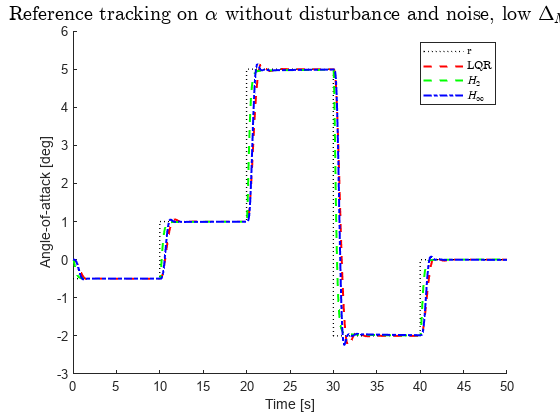

[yh2syn, t] = lsim(CL_h2syn_nw, [zeros(2, 5001); r; zeros(3, 5001)]', t);
[yh2n, t] = lsim(CL_h2n_nw, [zeros(2, 5001); r; zeros(3, 5001)]', t);
[yhinf, t] = lsim(CL_hinf_nw, [zeros(2,5001); r; zeros(3, 5001)]', t);
[ylqr, t] = lsim(Ge, r, t);

clf
figure
hold on
plot(t, r,"k:", 'LineWidth', 1)
plot(t, ylqr(:,1), "r--", t, yh2syn(:,2), "g--", t, yhinf(:,2), "b-.", 'LineWidth', 1.5)
legend("r", "LQR", "$H_{2}$", "$H_\infty$",'Interpreter','latex');
title("Reference tracking on $\alpha$ without disturbance and noise, low $\Delta_M$",'Interpreter','latex', 'FontSize', 15);
%title("Reference tracking on $\alpha$, $d = n = 0$, high $\Delta_M$",'Interpreter','latex', 'FontSize', 15);
ylabel("Angle-of-attack [deg]"), xlabel("Time [s]");
ylim([-3 6]); xlim([0 50]);

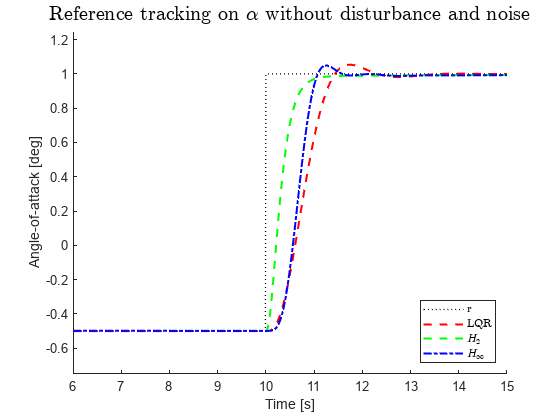


clf
figure
hold on
plot(t, r,"k:", 'LineWidth', 1)
plot(t, ylqr(:,1), "r--", t, yh2syn(:,2), "g--", t, yhinf(:,2), "b-.", 'LineWidth', 1.5)
legend("r", "LQR", "$H_{2}$", "$H_\infty$",'Interpreter','latex', "Location","southeast");
title("Reference tracking on $\alpha$ without disturbance and noise",'Interpreter','latex', 'FontSize', 15);
ylabel("Angle-of-attack [deg]"), xlabel("Time [s]")
ylim([-0.75 1.25]); xlim([6 15])

### Now consider the performance with added disturbance and noise

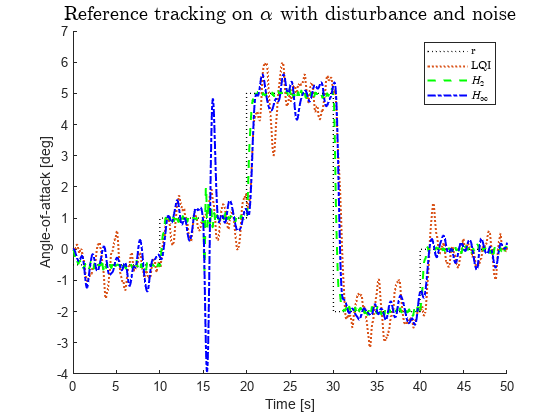

rng(1); % lock the rng

%d = randi([0, 1], [2, 5001]); % random discrete signals, magnitude 0.001
%n = randi([0, 1], [3, 5001]);
d = normrnd(0, 1, 2, 5001);
d(:,1500) = d(:,1500)*-100; % add a huge disturbance spike
d_small = 0.1*d;
d_large = 10*d;
n = randi([-1, 1], [3, 5001]);

%%%%% H2 and Hinf %%%%%
[yh2syn, t] = lsim(CL_h2syn_nw, [d_large; r; n]', t); % synthesised N_h2
[yh2n, t] = lsim(CL_h2n_nw, [d_large; r; n]', t); % nominal N_h2
[yhinf, t] = lsim(CL_hinf_nw, [d_large; r; n]', t);


%%%%%% LQI trajectories %%%%%
x_lqi = zeros(6, 5001);
xd_lqi = zeros(6, 5001);
u_lqi = zeros(3, 5001);
y_lqi = zeros(3, 5001);
nv = zeros(6,3); nv(2,1) = 1; nv(4,2) = 1; % noise selection vector

for k = 1:(length(t)-1)
    % disturbance and noise at every step
    dk = [tf2ss([0.9751, 0.2491], [1, 0.885, 0.1958])*d_small(:,k); 0];
    nk = Wn*n(:,k);
    % control input with noise
    u_lqi(:,k) = -K*(x_lqi(:,k) + nv*nk);
    % add disturbance and after first itirations to avoid windup
    if k > 10
        u_lqi(:,k) = u_lqi(:,k) + dk;
    end
    % calculate new state change
    xd_lqi(:,k) = A_lqr*x_lqi(:,k)...
                  + [B zeros(5,1); zeros(1, 3)]*u_lqi(:,k)...
                  + [zeros(1, 5) 1]'*r(:,k);
    x_lqi(:,k+1) = x_lqi(:,k) + xd_lqi(:,k)*0.01;
    % meassure
    y_lqi(:,k) = Ce*x_lqi(:,k);
end

%%%%% Plot %%%%%
clf
close all
hold on
plot(t, r, "k:", "LineWidth", 1)
plot(t, y_lqi(1,:), ":", t, yh2syn(:,2), "g--", t, yhinf(:,2), "b-.", "LineWidth", 1.5)
ylim([-4, 7]);
legend("r", "LQI", "$H_{2}$", "$H_\infty$",'Interpreter','latex');
title("Reference tracking on $\alpha$ with disturbance and noise",'Interpreter','latex', 'FontSize', 15);
ylabel("Angle-of-attack [deg]"), xlabel("Time [s]")

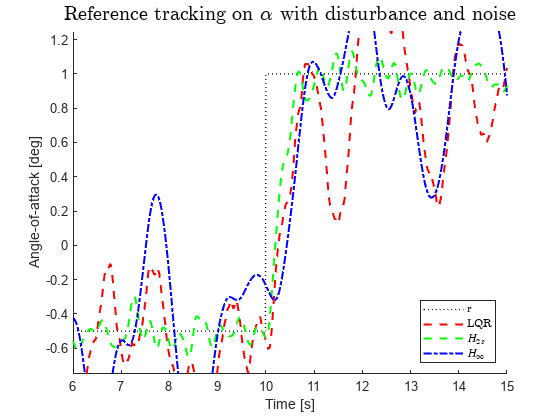

figure()
hold on
plot(t, r,"k:", 'LineWidth', 1)
plot(t, y_lqi(1,:), "r--", t, yh2syn(:,2), "g--", t, yhinf(:,2), "b-.", 'LineWidth', 1.5)
legend("r", "LQR", "$H_{2s}$", "$H_\infty$",'Interpreter','latex', "Location","southeast");
title("Reference tracking on $\alpha$ with disturbance and noise",'Interpreter','latex', 'FontSize', 15);
ylabel("Angle-of-attack [deg]"), xlabel("Time [s]")
ylim([-0.75 1.25]); xlim([6 15])